spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

nObs = size(spectra, 1);
mObs = size(spectra, 2);

lambdaEnd = lambdaStart + (nObs-1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';


infoMatrix = zeros(2, mObs)'

infoMatrix =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


for k = 1:1:mObs
    s = spectra(:, k);
    [sHa, idx] = min(s);
    lambdaHa = lambda(idx);
    infoMatrix(k, 1) = lambdaHa;
    infoMatrix(k, 2) = idx;
end

lambdaPr = 656.28;
SpeedOfLight = 299792.458;

speed = zeros(mObs, 1);
z = zeros(mObs, 1);

for i = 1:1:mObs
    z(i) = (infoMatrix(i,1)/lambdaPr) - 1;
    if z(i) > 0
    end
    speed(i) = z(i)*SpeedOfLight;
end


fg1 = figure;
set(fg1, 'Visible', 'on');
movaway = []


movaway =

     []




for j = 1:1:mObs
    if z(j) > 0
        plot(lambda, spectra(:, j), 'LineWidth', 3)
        movaway = [movaway, starNames(j)]
    else
        plot(lambda, spectra(:, j), '--', 'LineWidth', 1)
    end
    hold on
end

movaway = 1×1 cell array
    {'HD5211'}


movaway = 1×2 cell array
    {'HD5211'}    {'HD56030'}


movaway = 1×3 cell array
    {'HD5211'}    {'HD56030'}    {'HD94028'}



movaway = movaway'

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


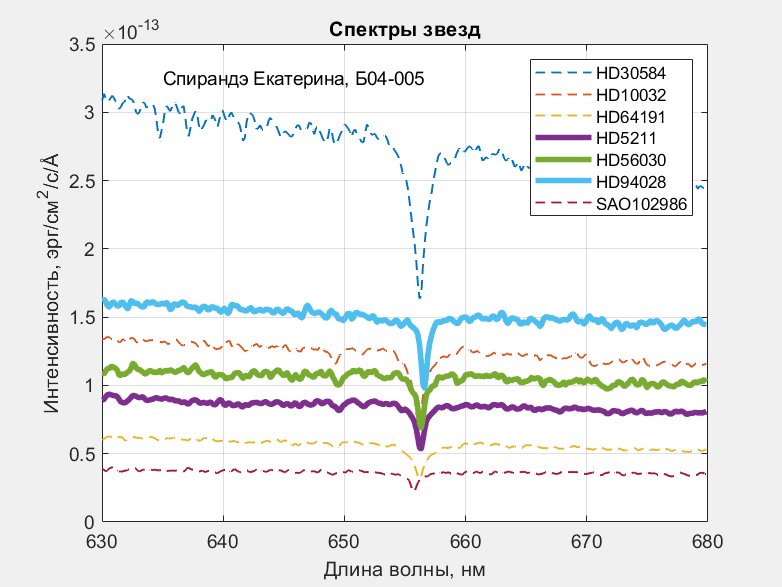

legend(starNames)
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/c/', char(197)])
title('Спектры звезд')
text(635, 3.25*10^(-13), 'Спирандэ Екатерина, Б04-005')
grid on
hold off

saveas(fg1, 'spectra.png');